# 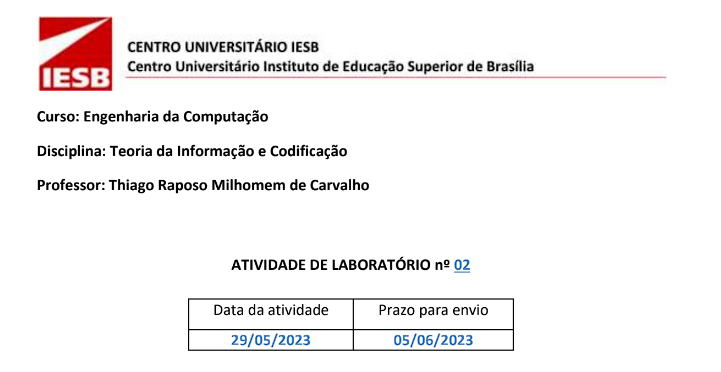

### **            Aluno: Diego Vieira Santos                    Matricula: 2012082035** 

# Introdução

Nesta atividade iremos abordar o uso do código corretor de hamming e como ele pode ser utilizado para corrigir erros de bit.

# Funcionamento do código corretor de erro de Hamming

O emissor nos envia uma mensagem e precisamos identificar sua palavra código, sabemos que pode ocorrer erro de bit ao passar pelo canal, desta forma utilizamos este código para corrigir este erro de bit (caso seja apenas 1 erro de bit) e com isso obteremos a palavra código original sem erros de bit

Para se ter a palavra código precisamos saber qual foi a mensagem enviada pelo emissor, com esse dado teremos


$$\mathit{\mathbf{c}}=\mathit{\mathbf{m}}\bullet G$$


Ao enviar uma palavra código, será recebido no destino uma palavra código com rúido adicionado, ou seja:


$$\mathit{\mathbf{r}}=\mathit{\mathbf{c}}+\mathit{\mathbf{n}}$$


Após o recebimento deste rúido é feito o cálculo da síndrome:


$$\mathit{\mathbf{s}}={\mathit{\mathbf{r}}\bullet \;H}^T$$


Essa síndrome nos retorna uma linha que ao ser transposta ela equivale a coluna da matriz de verificação de paridade onde ocorreu o erro de bit, caso seja nula então esta palavra código não possui erro de bit pois a matriz de paridade consiste em representações binárias dos números de 1 a 7.

Ao somarmos a palavra código com ruído com um vetor $n_i$ que possui apenas zeros em seus índices, exceto no indice que ocorreu o erro, então teremos a palavra código com erro corrigido, ou seja:


$$\hat{\mathit{\mathbf{c}}} =r+n$$


Se o procedimento falhar e encontrarmos uma palavra código com erro corrigido $\hat{\mathit{\mathbf{c}}}$ diferente da palavra código $\mathit{\mathbf{c}}$ então esta mensagem possui mais de um erro de bit.

# Códigos Corretores de Erro - Código de Hamming

Nesta atividade, vamos realizar a codificação de canal (detecção e correção de erros de bit),

implementando o Código de Hamming (7,4). Para isto, utilizaremos as seguintes matrizes

geradora ($G$) e de verificação de paridade ($H$), respectivamente:

G = [1 1 0 1 0 0 0 ; 0 1 1 0 1 0 0 ; 0 0 1 1 0 1 0 ; 0 0 0 1 1 0 1]

G =      1     1     0     1     0     0     0
     0     1     1     0     1     0     0
     0     0     1     1     0     1     0
     0     0     0     1     1     0     1


H = [1 0 1 1 1 0 0 ; 0 1 0 1 1 1 0 ; 0 0 1 0 1 1 1 ]

H =      1     0     1     1     1     0     0
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1


Ou seja, conforme visto, mensagens de 4 bits, na forma $m=\left\lbrack m_1 \;m_2 \;m_3 \;m_4 \right\rbrack$,serão codificadas,

gerando palavras código de 7 bits, na forma $c=\left\lbrack c_{\;1} \;c_2 \;c_3 \;c_4 \;c_5 \;c_6 \;c_7 \right\rbrack \;$, utilizando a relação:


$$c=m\bullet G$$


Como sabemos, a palavra código enviada pode sofrer erros de bit ao trafegar pelo canal de

comunicação, de modo que a palavra binária recebida, r, é dada por:


$$r=c+n$$


onde $n=\left\lbrack n_1 \;n_2 \;n_3 \;n_4 \;n_5 \;n_6 \;n_7 \right\rbrack$ representa o vetor de ruído, de modo que $n_i =1$quando

ocorre erro de bit na i-ésima posição (1 ≤ i ≤ 7) da palavra código c enviada. Assim, calcula-se

a síndrome s, dada por:


$$s=r\bullet H^T$$


onde $H^T$ é a transposta de $H$. Lembre-se que a síndrome indica a posição em que houve erro de

bit – até o limite de 1 erro de bit para o código de Hamming (7,4).

# Legenda


$$\begin{array}{l}
G\;=\mathrm{Matriz}\;\mathrm{geradora}\\
H\;=\mathrm{Matriz}\;\mathrm{de}\;\mathrm{verificação}\;\mathrm{de}\;\mathrm{paridade}\\
H^T =\mathrm{Matriz}\;\mathrm{de}\;\mathrm{verificação}\;\mathrm{de}\;\mathrm{paridade}\;\mathrm{transposta}\\
m\;=\mathrm{Mensagem}\;\mathrm{que}\;\mathrm{será}\;\mathrm{enviada}\;\mathrm{pelo}\;\mathrm{emissor}\\
c\;=\mathrm{Palavra}\;\mathrm{código}\\
r=\mathrm{Palavra}\;\mathrm{código}\;\mathrm{com}\;\mathrm{ruído}\;\mathrm{adicionado}\\
n=\mathrm{Ruído}\\
s=\mathrm{Síndrome}\;\\
\hat{\mathit{\mathbf{c}}} =\mathrm{Palavra}\;\mathrm{código}\;\mathrm{com}\;\mathrm{erro}\;\mathrm{corrigido}\\
d_{\mathrm{min}} =\mathrm{Distancia}\;\mathrm{mínima}
\end{array}$$
 

# Rotina para o código corretor de erro

Definindo mensagem (vetor binário) $\mathit{\mathbf{m}}$ e a posição $\mathit{\mathbf{n}}$  em que ocorrerá o erro de bit

m = [0 1 1 0];
n = [1 0 0 0 0 0 0];

Utilizando algoritmo que retorna a palavra código $\mathit{\mathbf{c}}$gerada com a matriz $\mathit{\mathbf{G}}$, o vetor $\mathit{\mathbf{r}}$com um erro de bit, a síndrome $\mathit{\mathbf{s}}$ e a palavra código corrigida ${\mathit{\mathbf{c}}}_2$.

[c,r,s,c2] = hamming(m,n);

Definindo matrizes geradora, de verificação de paridade e verificação de paridade transposta respectivamente:

G = [1 1 0 1 0 0 0 ; 0 1 1 0 1 0 0 ; 0 0 1 1 0 1 0 ; 0 0 0 1 1 0 1]

G =      1     1     0     1     0     0     0
     0     1     1     0     1     0     0
     0     0     1     1     0     1     0
     0     0     0     1     1     0     1


H = [1 0 1 1 1 0 0 ; 0 1 0 1 1 1 0 ; 0 0 1 0 1 1 1 ]

H =      1     0     1     1     1     0     0
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1


H_t = H'

H_t =      1     0     0
     0     1     0
     1     0     1
     1     1     0
     1     1     1
     0     1     1
     0     0     1


Encontrando a palavra código

c = mod(m * G , 2 )

c =      0     1     0     1     1     1     0


Encontrando a palavra recebida

r = c + n

r =      1     1     0     1     1     1     0


Calculando síndrome $\mathit{\mathbf{s}}$

s = mod(r * H_t , 2 )

s =      1     0     0


Definindo a palavra código corrigida 

error_index = 0;
    
for i = 1 : 7
    if s(1) == H(1,i) && s(2) == H(2,i) && s(3) == H(3,i)
       error_index = i;
    end
end

c2 = r;
if(error_index ~= 0)
    if(r(error_index) == 0)
        c2(error_index) = 1;
    else
        c2(error_index) = 0;
    end
end

c2

c2 =      0     1     0     1     1     1     0


Limpando workspace para processos futuros

clear;

# Observações

#### 1) Qual a distância mínima $d_{\mathrm{min}}$ para o código de Hamming (7,4)? O que isso significa?

    A distância mínima para um código de Hamming(7,4) é de 3, isso significa que para cada código valido existe uma distancia de 3 bits para um outro código valido, exemplo:

    Supondo $c_1$e $c_2$ como duas palavras códigos válidas:

    
$$c_1 =\left\lbrack \;1\;0\;0\;1\;1\;0\;0\right\rbrack$$


    
$$c_2 =\left\lbrack 1\;0\;1\;1\;0\;1\;0\right\rbrack$$


    
$$c_1 \oplus c_2 =\left\lbrack 0\;0\;1\;0\;1\;1\;0\right\rbrack$$


    Ao fazer essa comparação encontramos que 3 bits diferem entre as duas palavras.

#### 2) Qual a capacidade de correção desse código? (Até quantos erros de bit é capaz de

#### corrigir?)

    O código de Hamming(7,4) é capaz de corrigir apenas 1 erro de bit.

#### 3) O que seu algoritmo retornaria se, por exemplo, ocorressem 3 erros de bit? Faça esse

#### teste (calcule a síndrome nesse caso) e explique o resultado. Para isso, troque, por

#### exemplo, os 3 primeiros bits de c (caso em que n = [1 1 1 0 0 0 0]). Explique o que

#### ocorre e qual seria a palavra “corrigida” nesse caso.

    Testando para a mesma mensagem da rotina

m = [0 1 1 0];

    Porém com 3 erros de bit no inicio

n = [1 1 1 0 0 0 0];

    Aplicando o código de correção de erro de Hamming

[c,r,s,c2] = hamming(m,n);

    Obtendro a síndrome $\mathit{\mathbf{s}}$

s

s =      0     1     1


    A síndrome retornou um vetor equivalente a sexta coluna da matriz de paridade, porém nem aconteceu erro de bit nessa posição, isso ocorre pois o codigo de Hamming(7,4) é capaz de corrigir apenas um erro de bit.

    A palavra "corrigida" acabou adicionando mais erros de bit na palavra código, desta forma não seria possível saber qual foi a palavra enviada pelo emissor utilizando este método.

# Algoritmo corretor de erro utilizando código de Hamming

function [c,r,s,c2] = hamming(m,n)

    G = [1 1 0 1 0 0 0 ; 0 1 1 0 1 0 0 ; 0 0 1 1 0 1 0 ; 0 0 0 1 1 0 1];
    H = [1 0 1 1 1 0 0 ; 0 1 0 1 1 1 0 ; 0 0 1 0 1 1 1 ];
    H_t = H';
    
    c = mod(m * G,2);
    
    r = mod(c + n,2);
    
    s = mod(r * H_t,2);
    
    error_index = 0;
    
    for i = 1 : 7
        if s(1) == H(1,i) && s(2) == H(2,i) && s(3) == H(3,i)
           error_index = i;
        end
    end

    c2 = r;
    if(error_index ~= 0)
        if(r(error_index) == 0)
            c2(error_index) = 1;
        else
            c2(error_index) = 0;
        end
    end
    
    
end


## Conclusões gerais

O trabalho realizado foi bem interessante e satisfatório, com ele foi possível entender melhor o funcionamento do código de Hamming e como funciona sua aplicação na prática.